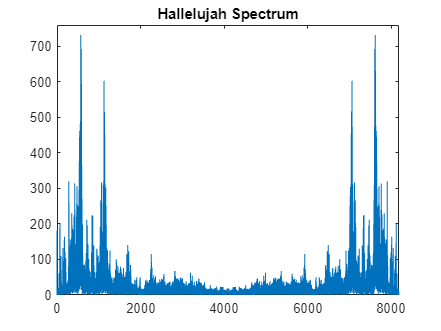

% Starting point for PV processing
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760]) 


% Call function to take STFTs of sequence PVAnalysis() 
[Moduli, Phase] = PVAnalysis(x, 512, 256)  

Window Size: 512
Hop Size: 256
# Windows: 255

Moduli =     0.0021    0.0473    0.1225    0.1545    0.1532    0.1587    0.1262    0.0171    0.0212    0.0457    0.0987    0.0462    0.0981    0.0841    0.0598    0.0637    0.0551    0.0177    0.1098    0.1873    0.2296    0.1688    0.1391    0.1421    0.1471    0.1762    0.1647    0.0850    0.0243    0.0720    0.0606    0.0405    0.0187    0.0660    0.1202    0.0608    0.0739    0.0645    0.0466    0.0739    0.0380    0.0868    0.1458    0.0437    0.1143    0.0217    0.1130    0.1830    0.0581    0.1142
    0.0606    0.0797    0.1146    0.1159    0.0974    0.0660    0.0630    0.1982    0.2075    0.1585    0.1021    0.0775    0.1360    0.0998    0.0136    0.0335    0.0372    0.0823    0.0651    0.0226    0.0948    0.1588    0.1501    0.1097    0.1080    0.0994    0.0712    0.0456    0.0274    0.0032    0.0490    0.0587    0.0237    0.0216    0.0183    0.0656    0.0466    0.0767    0.1054    0.1096    0.1409    0.1256    0.0331    0.0565    0.0480    0.1266    0.1174    0.0335    0.0718

Phase =     3.1416   -2.3135    0.7269   -2.4162    0.8795   -2.4515    0.1679    2.3372    2.5033   -0.7585    2.8786    3.1181   -0.1159    0.7019   -2.5669   -1.9052    1.3363    2.5560   -1.3523    2.0056   -0.9542    1.7065   -1.9251    2.4287    0.3646   -1.7105    1.9439   -0.4585   -1.3500   -2.9238    0.7597   -1.1282    2.8458    1.5226   -1.4752    1.5486    2.6971   -0.2800   -1.2709    2.2386   -1.3015    1.6633   -1.2189    0.8184    2.9305    0.0672    1.7281   -0.8205   -2.7445    2.0434
    3.1416    0.3503    2.9066   -0.3441    3.0182    0.1319    1.3744   -1.6993    1.5288   -1.3786    1.9192    2.4709   -0.4977   -2.7575    0.0129    1.1618   -0.0741    2.1096   -1.7062   -1.4511    1.0788   -1.4813    2.3317    0.0041   -2.5300    0.6238    3.0866   -0.2704    3.1395    1.1625   -0.1966    3.0129    0.5487   -0.3733    2.4517   -1.5648    1.4041    2.4493   -1.1090    1.1709   -2.4199    0.5816   -2.4487   -1.9827    2.6526    0.1373    2.9634   -1.6667    0.5804 

temp = reshape(Moduli, 1, []) 

temp =     0.0021    0.0606    0.0203    0.0063    0.0232    0.1168    0.1241    0.0514    0.1860    0.1961    0.2352    0.1637    0.0424    0.3039    0.2442    0.1088    0.0005    0.1939    0.2194    0.5780    0.3913    0.2397    0.2752    0.1848    0.2994    0.0711    0.1254    0.5623    0.5571    0.2312    0.4079    0.0360    0.0773    0.1256    0.0031    0.0265    0.0394    0.0025    0.0250    0.0066    0.0231    0.3549    0.2660    0.3718    0.0250    0.0517    0.0507    0.0862    0.1221    0.0376


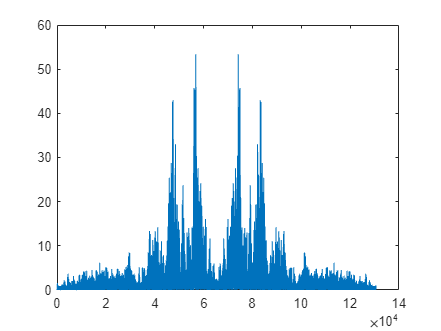

plot(temp)